# Introduction

This challenge focuses on ensuring patient health through data. You are tasked to train a model that takes as input the patient record data and outputs a prediction of whether or not the patient has Diabetes Mellitus, which could inform treatment in the ICU. Learn more about and download the challenge dataset by registering for [this Kaggle competition](https://www.kaggle.com/competitions/widsdatathon2021/data) and downloading the training dataset. You may also choose to download the data dictionary, which contains additional information about the dataset.

This tutorial uses an example dataset to show you how to complete the steps of building your own regression model, so **make sure to replace this dataset with the challenge dataset before making your own models. **

# Load & Prepare Data

This dataset presents an opportunity to learn about the data modelling and processing challenges a real-world data problem brings. This tutorial will show some basic methods to handle data challenges, but you can learn about more methods by going through this [Data Science Tutorial video series](https://www.mathworks.com/videos/series/data-science-tutorial.html).

## Step 1: Load Data

Use the [readtable](https://www.mathworks.com/help/matlab/ref/readtable.html?) function to read the files and store it as tables. You can also import data using the MATLAB® [Import tool](https://www.mathworks.com/help/matlab/import_export/select-spreadsheet-data-interactively.html).

fullSet = readtable('exampleTrain.csv');

Once imported, preview the data to get a sense of what you're working with.

head(fullSet)

      Var1      Var2      Var3      Var4     Var5        Var6       Var7      Var8       Var9     Var10    Var11     Var12      Var13     Var14    Var15     Var16     Var17      Var18     Var19     Var20      Var21    Var22     Var23      Var24    Var25      Var26      Var27     Var28      Var29     Var30      Var31      Var32     Var33      Var34     Var35     Var36     Var37<

## Step 2: Clean Data

The biggest challenge with real datasets is that they are messy. Data transformation and modelling will be the key area to work on to avoid overfitting the problem.

Using the *summary* function, analyze the types of the predictors, some statistics about each predictor, and the number of missing values for each predictor column. This can help you decide how to clean your dataset.

summary(fullSet);


fullSet: 130157×181 table

Variables:

    Var1: double
    Var2: double
    Var3: cell array of character vectors
    Var4: double
    Var5: double
    Var6: cell array of character vectors
    Var7: double
    Var8: double
    Var9: double
    Var10: double
    Var11: double
    Var12: cell array of character vectors
    Var13: double
    Var14: double
    Var15: double
    Var16: double
    Var17: double
    Var18: double
    Var19: double
    Var20: cell array of character vectors
    Var21: double
    Var22: double
    Var23: cell array of character vectors
    Var24

There are many different approaches to work with the missing values and predictor selection. We will go through one of the basic approaches, but you can also refer to this document to learn about other methods: [Clean Messy and Missing Data](https://www.mathworks.com/help/stats/find-missing-data.html).

*Note: This approach of data cleaning demonstrated is chosen arbitrarily to cut down number of predictor columns.*

**Remove the character columns of the table**

Many machine learning algorithms only allow for numeric values as the input arguments, so you can remove variables of any non-numeric type. Those are imported as cell arrays, so check which columns are of type 'cell' and remove them.

columnDataTypes = varfun(@iscell, fullSet, OutputFormat="cell");
nonNumericCols = cell2mat(columnDataTypes);
nonNumColNames = fullSet.Properties.VariableNames(nonNumericCols);

fullSet = removevars(fullSet, nonNumColNames)

fullSet = 130157×144 table
      Var1       Var2    Var4      Var5       Var7      Var8       Var9     Var10    Var11    Var13     Var14    Var15     Var16     Var17      Var18     Var19    Var21    Var22    Var24    Var25      Var26      Var27    Var29      Var30      Var31       Var32     Var33      Var34     Var35     Var36     Var37    Var38     Var39      Var40      Var41       Var42

**Remove extreme values from all the vitals predictors**

Some data points may be on the extreme low or high end of what you'd expect to see, which might cause unexpected behavior when this data is used to train a model. Use the Clean Outlier Data live task to remove these outlier data points. 

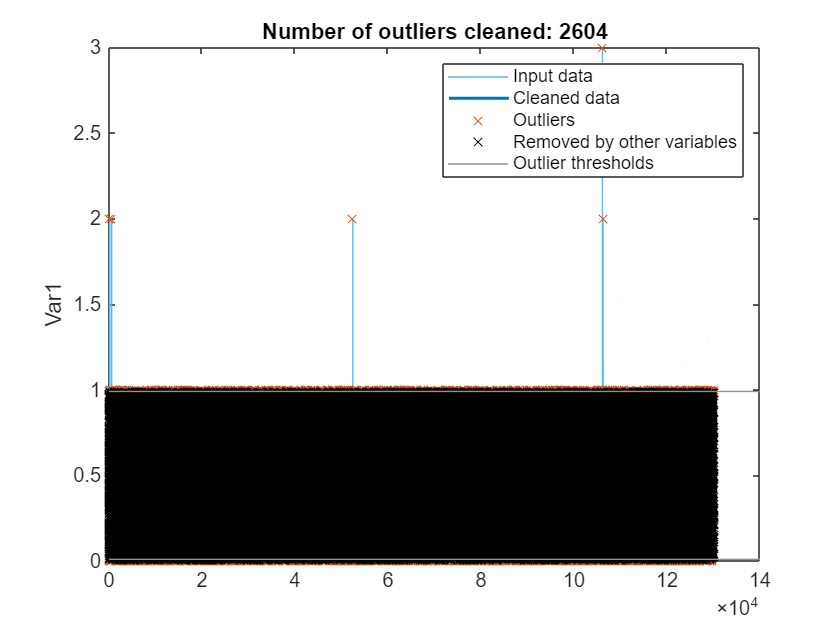

% Remove outliers
[cleanedSet,outlierIndices,outliersForPlot2,lo2,hi2] = rmoutliers(fullSet, ...
    "percentiles",[1 99]);

% Display results
figure
plot(fullSet.Var1,"SeriesIndex",6,"DisplayName","Input data")
hold on
plot(find(~outlierIndices),cleanedSet.Var1,"SeriesIndex",1,"LineWidth",1.5, ...
    "DisplayName","Cleaned data")

% Plot outliers
plot(find(outliersForPlot2(:,1)),fullSet.Var1(outliersForPlot2(:,1)),"x", ...
    "SeriesIndex",2,"DisplayName","Outliers")

% Plot data in rows where other variables contain outliers
mask = outlierIndices & ~outliersForPlot2(:,1);
plot(find(mask),fullSet.Var1(mask),"x","SeriesIndex","none", ...
    "DisplayName","Removed by other variables")

% Plot outlier thresholds
plot([xlim missing xlim],[lo2.Var1 lo2.Var1 missing hi2.Var1 hi2.Var1], ...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

hold off
title("Number of outliers cleaned: " + nnz(outliersForPlot2(:,1)))
legend
ylabel("Var1")

clear outliersForPlot2 lo2 hi2 mask

**Remove the rows which have at least 10 missing values**

The other assumption I made is the observations (rows) which have missing predictor values can be removed.

cleanedSet = rmmissing(cleanedSet,1,"MinNumMissing",10);

**Move response variable to the end**

Last, move our label predictor *OutputVar* to the last column of the table because for some algorithms in MATLAB the last column is the default response variable.

cleanedSet = movevars(cleanedSet,'OutputVar')

cleanedSet = 26734×144 table
      Var1      Var2    Var4     Var5       Var7      Var8       Var9     Var10    Var11    Var13     Var14    Var15     Var16     Var17      Var18     Var19    Var21    Var22    Var24    Var25     Var26      Var27    Var29     Var30      Var31      Var32     Var33      Var34      Var35     Var36     Var37    Var38     Var39      Var40      Var41      Var42

## Step 3: Create Training Data

Once the data is clean, separate the output variable *OutputVar* from the dataset and create two separate tables. *XSet:* Predictor data, *YSet*: Class labels

XSet = removevars(cleanedSet,{'OutputVar'});
YSet = cleanedSet.OutputVar;

## Step 4: Create Test Data

Set aside a portion of the dataset to evaluate your trained models, the rest will be used for training. You can adjust how much you hold out for testing. 

c = cvpartition(height(XSet), 'Holdout', 0.2);

idxTrain = training(c);
XTrain = XSet(idxTrain,:);
YTrain = YSet(idxTrain);

idxTest = test(c);
XTest = XSet(idxTest,:);
YTest = YSet(idxTest);

## Step 5: Train a Model

In MATLAB you can train a classification model using two different methods:

- Using MATLAB machine learning algorithm functions

- Using the Classification Learner app

## Option 1: Using custom algorithms

A Binary classification problem can be approached using various algorithms like decision tress, svm, and logistic regression. Here I train using [fitclinear](https://www.mathworks.com/help/stats/fitclinear.html?) classification model. It trains the linear binary classification models with high dimensional predictor data.

Convert the table to a numeric matrix because *fitclinear* function takes only numeric matrix as an input argument.

XTrainMat = table2array(XTrain);
XTestMat = table2array(XTest);

Using Name-Value options, let's set the solver as sparsa (Sparse Reconstruction by Separable Approximation), which has default *lasso* regularization. Check out the [*fitclinear*](https://www.mathworks.com/help/stats/fitclinear.html?) document to learn more about all of the input argument options.

Mdl = fitclinear(XTrainMat,YTrain,'ObservationsIn','rows',...
    'Solver','sparsa');

**Predict on the Test Set**

Once we have your model ready, you can perform predictions on your test set using predict function. It takes as input the fitted model and test data. The output is the predicted labels and scores. You can then evaluate how well the model performs by plotting a confusion matrix, which compares the predicted values to the actual values. Since this is just a dummy dataset, the performance is very poor, but when you start working with real data and testing different model configurations, you should start to see significant improvement. An ideal model would show two dark blue squares, one in the top-left and one in the bottom-right, to indicate that the model predicted correctly every time. 

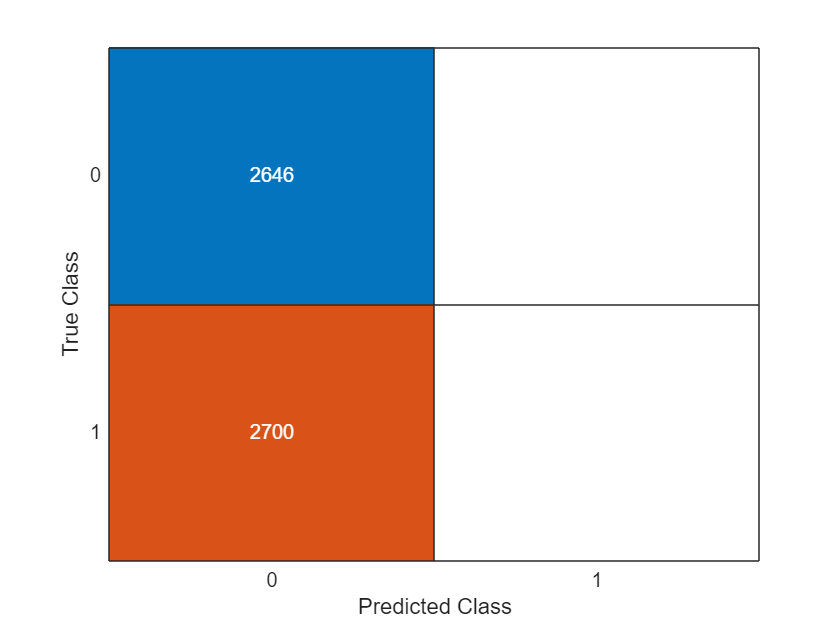

[label,scores] = predict(Mdl,XTestMat);
confusionchart(YTest, label);

This model appears to predict 0 every time, indicating we should make some adjustments to the data, machine learning algorithm, or training options. 

## Option 2: Using Classification Learner App

Second method of training the model is by using the Classification Learner app. It lets you interactively train, validate and tune classification model. Get started with it by following the steps below, and check out the [documentation](https://www.mathworks.com/help/stats/classification-learner-app.html) to learn more. 

- On the ***Apps*** tab, in the Machine Learning group, click ***Classification Learner***.

- Click ***New Session*** and select data (***XTrain***) from the workspace. Specify the response variable as 'From workspace' (***YTrain***).

- Select the validation method to avoid overfitting. You can either choose ***holdout validation*** or ***cross-validation,*** selecting the number of k-folds.

- Hit ***Start Session***

- On the ***Classification Learner tab***, in the ***Model Type*** section, select the algorithm to be trained (e.g. *logistic regression, All svm, All Quick-to-train).*

- You can use the ***Options*** section to customize your algorithms throuch PCA, Feature Selection, or other advanced options. 

- Once all required options are selected, click ***Train***.

- The history window on the left displays the different models trained and their accuracy.

- Performance of the model on the validation data can be evaluated by ***Confusion Matrix ***plot or other options on the ***Plots and Results*** section of the toolstrip.

- To make predictions on the test set, export the model by selecting ***Export Model*** on *Classification Learner tab*.

**Predict on the Test Set**

The exported model is saved as *trainedModel* in the workspace. You can then predict labels and scores using *predictFcn*.

The *label* is the predicted labels on Test set. *Scores* are the scores of how confident the model is that the correct output is each class. You can then evaluate how well the model performs by plotting a confusion matrix, which compares the predicted values to the actual values.

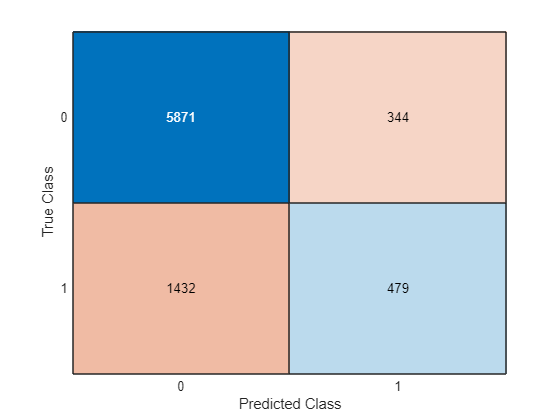

[label,scores] = trainedModel.predictFcn(XTest);
confusionchart(YTest, label);

This shows that the model is predicting 0 more often than it should. You should play around with other metrics and visualizations to showcase the quality of your model.

# Additional Resources

- [Data Science Tutorial](https://www.mathworks.com/videos/series/data-science-tutorial.html)

- [Missing Data in MATLAB](https://www.mathworks.com/help/releases/R2019b/matlab/data_analysis/missing-data-in-matlab.html)

- [Supervised Learning Workflow and Algorithms](https://www.mathworks.com/help/releases/R2019b/stats/supervised-learning-machine-learning-workflow-and-algorithms.html)

- [Train Classification Models in Classification Learner App](https://www.mathworks.com/help/stats/train-classification-models-in-classification-learner-app.html)

- [Export Classification Model to Predict New Data](https://www.mathworks.com/help/stats/export-classification-model-for-use-with-new-data.html)

- [8 MATLAB Cheat Sheets for Data Science](https://www.mathworks.com/campaigns/offers/data-science-cheat-sheets.html)